addpath("C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6\import_data")
warning('off','all')

figure;
AoA = [2 4 6]

AoA =      2     4     6


M = [0.70 0.75 0.80 0.85 0.90 0.95 1.00 1.10 1.20 1.40 1.60 1.80 2.00]

M =     0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.1000    1.2000    1.4000    1.6000    1.8000    2.0000


filenamestring = ".\graphs\EquStress-Graph-2deg.png"

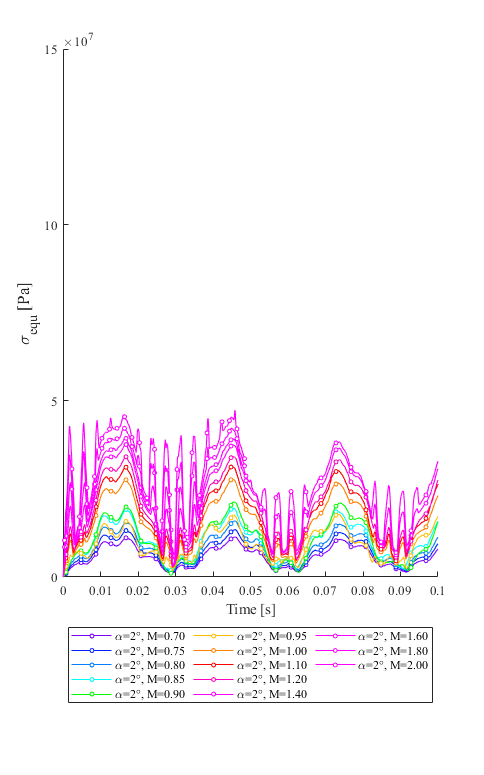

filenamestring = ".\graphs\EquStress-Graph-4deg.png"

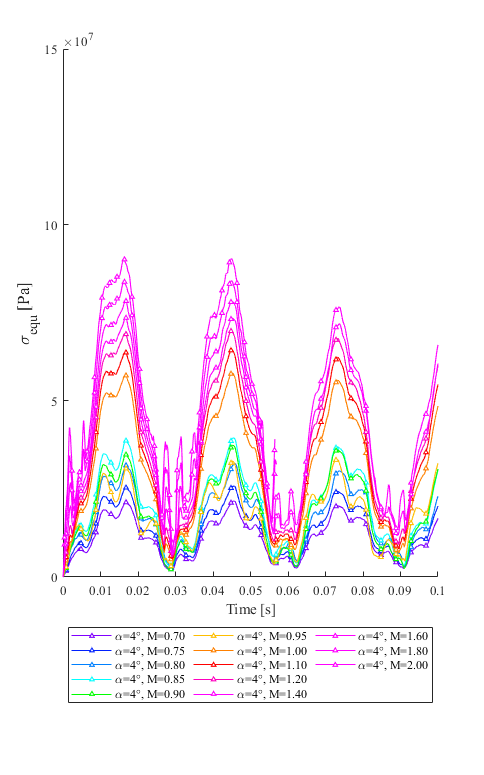

filenamestring = ".\graphs\EquStress-Graph-6deg.png"

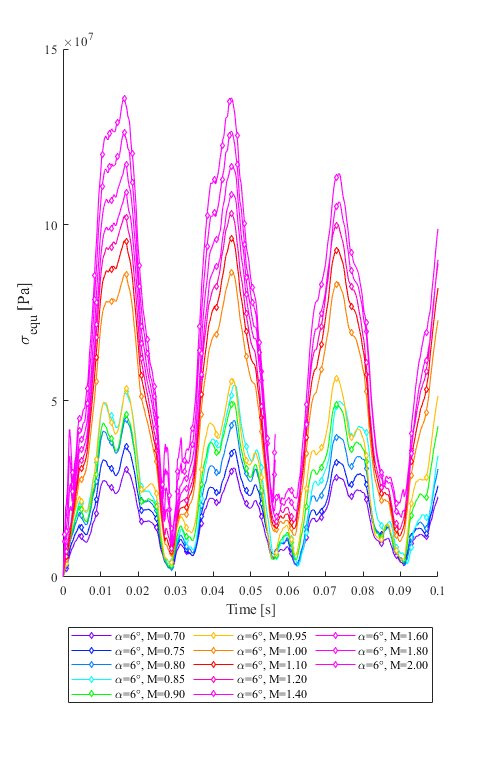



colorbank = {[128, 0, 255]/256 [0, 32, 255]/256 [0, 128, 255]/256 [0, 255, 255]/256 [0, 255, 0]/256 [255, 191, 0]/256 [255, 128, 0]/256 [255, 0, 0]/256 [255, 0, 191]/256 'm' 'm' 'm' 'm'};
markerbank = {'o' '^' 'd'};
markersize = 3; markerindices = 5:20:1000; markerfacecolor = 'w'; linewidth = 0.8;

StructData = cell(length(AoA),length(M));
EquStressLines = gobjects(size(StructData));
LegendLabels = string(size(StructData));

for ind_AoA=1:length(AoA)
    figure;
    for ind_M=1:length(M)
        StructData{ind_AoA,ind_M} = importStructData(AoA(ind_AoA), M(ind_M));
        EquStressLines(ind_AoA,ind_M) = line(StructData{ind_AoA,ind_M}.Time, StructData{ind_AoA,ind_M}.EquStress);
        EquStressLines(ind_AoA,ind_M).Marker = markerbank{ind_AoA};
        EquStressLines(ind_AoA,ind_M).MarkerSize = markersize;
        EquStressLines(ind_AoA,ind_M).MarkerIndices = markerindices;
        EquStressLines(ind_AoA,ind_M).MarkerFaceColor = markerfacecolor;
        EquStressLines(ind_AoA,ind_M).LineWidth = linewidth;
        EquStressLines(ind_AoA,ind_M).Color = colorbank{ind_M};
        LegendLabels(ind_AoA,ind_M) = "\alpha=" + StructData{ind_AoA,ind_M}.AoA + "°, M=" + StructData{ind_AoA,ind_M}.MachNumber;
    end



xlim([0,0.1])
xlabel("Time [s]",FontSize=11)
ylabel("\sigma_{equ} [Pa]",FontSize=13)
ylim([0,15e+7])

legend(LegendLabels(ind_AoA,:),Location="southoutside",NumColumns=3)
figposition = [10,10,500,800];
set(gcf,"Position",figposition);
set(gca,'FontName','Times');

filenamestring=".\graphs\EquStress-Graph-" + num2str(AoA(ind_AoA)) + "deg.png"
exportgraphics(gcf,filenamestring,"Resolution",300,"BackgroundColor","none",ContentType="vector")
end